# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**January 20, 2025**

# PART 2 - Design of a Controller with Requirements on the Performance against Disturbances 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

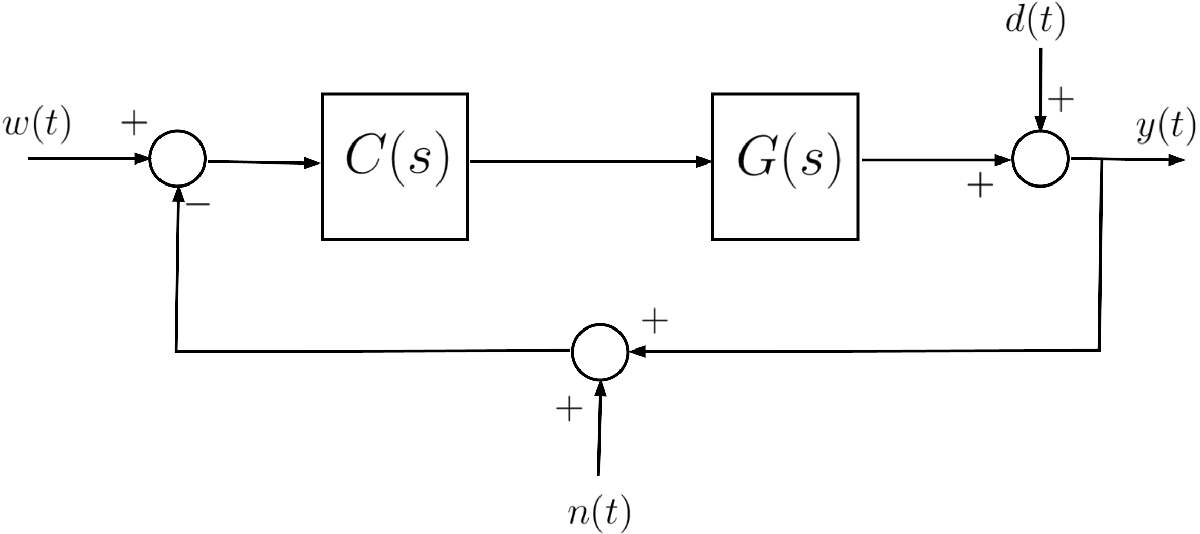	

where $G(s)$ is given by                


$$G(s) = 2 \frac{(1+10\,s)}{(1+s)}$$


### Assignment 		

**A1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $|e(\infty)| \le 0.01$ for $w(t) = \mathbf{1}(t)$ and $d(t) = 0$;

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[1.0\cdot 10^{-5}\,,\; 1.0\cdot 10^{-3}\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/100$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[2.0,\,10.0\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/10$.	

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \ge 100.0\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/100$.

- Finally, $G(s)$ is not a strictly proper transfer function, but both the controller $C(s)$ and the open-loop $L(s)$ transfer functions have to be strictly proper.

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

The system described by the transfer function $G(s)$ is minimum-phase. Hence we proceed by a standard loop-shaping design of the controller $C(s)$through the following logical steps:

### Requirements Analysis

**Requirement (A1.2)**: The transfer function $T_{d,\,y}(s)$ from the input $d(t)$ to the output $y(t)$ is the sensitivity function $S(s)$ [refer to Part 9 of the course material, slides 34--36, 45--48]:


$$T_{d,\,y}(s) = S(s) = \frac{1}{1+L(s)}$$


Consider the frequency response associated with $T_{d,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 48 of the course material:


$$\left\vert T_{d,\,y}(j \omega) \right\vert = \left\vert S(j \omega)\right\vert = \frac{1}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
\frac{1}{\left\vert L(j\omega)\right\vert}\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
1\, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (A1.2)


$$d(t) = D \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[1.0\cdot 10^{-5}\,,\; 1.0\cdot 10^{-3}\right]\;\text{rad/s}$$


Hence, to obtain $\left\vert y_{d,\,\infty}\right\vert \le \frac{D}{100}$, we need to guarantee that $\left\vert S(j\,\bar \omega)\right\vert \le \frac{1}{100}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \ge 100,\; \forall \bar \omega \in \left[1.0\cdot 10^{-5}\,,\; 1.0\cdot 10^{-3}\right]\;\text{rad/s}$$


**Requirement (A1.3): **The transfer function $T_{n,\,y}(s)$ from the input $n(t)$ to the output $y(t)$ is the complementary sensitivity function $F(s)$ with a change of sign [refer to Part 9 of the course material, slides 34--36, 37--40]:


$$T_{n,\,y}(s) = -F(s) = -\frac{L(s)}{1+L(s)}$$


Analogously to what has been done above, consider the frequency response associated with $T_{n,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 40 of the course material:


$$\left\vert T_{n,\,y}(j \omega) \right\vert = \left\vert F(j \omega)\right\vert = \frac{\left\vert L(j\omega)\right\vert}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
1\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
\left\vert L(j \omega)\right\vert \, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (A1.3)


$$n(t) = N \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[ 2,\; 10 \right] \; \text{rad/s}$$


Hence, to obtain $\left\vert y_{n,\,\infty}\right\vert \le \frac{N}{10}$, we need to guarantee that $\left\vert F(j\,\bar \omega)\right\vert \le \frac{1}{10}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{10},\; \forall \bar{\omega} \in \left[ 2,\; 10 \right] \; \text{rad/s}$$


**Requirements (A1.4): **Analogously to what has been done analysing the requirement (A1.3), to obtain $\left\vert y_{n,\,\infty}\right\vert \le \frac{N}{100}$ given $n(t) = N \sin \left(\bar{\omega}\,t\right) \cdot 1(t)$ with $\bar{\omega} \ge 100 \, \text{rad/s}$, we need to guarantee that $\left\vert F(j\,\bar \omega)\right\vert \le \frac{1}{100}\,,\; \bar \omega \ge 100.0 \,\text{rad/s}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{100},\; \forall \bar{\omega} \ge 100 \,\; \text{rad/s}$$


**Requirement (A1.1): **This requirement implies that the **open-loop transfer function** $L(s)$ should be of **type **$\mathbf{g=0}$. The transfer function $T_{w,\,e}(s)$ from the input $w(t)$ to the error $e(t)$ is the sensitivity function $S(s)$ [refer to Part 9 of the course material, slides 34--36, 45--48]:


$$T_{w,\,e}(s) = S(s) = \frac{1}{1+L(s)}$$



$$w(t) = 1(t) \;\Longrightarrow\; e(\infty) = \lim_{s \to 0} s\cdot S(s) \cdot \displaystyle \frac{1}{s} = \lim_{s \to 0}  S(s) = \lim_{s \to 0} \displaystyle \frac{1}{1+L(s)} = \displaystyle \frac{1}{1+\mu_{L}} \,,\quad \mu_{L} = L(0)$$


Thus:


$$|e(\infty)| \le 0.01 \; \Longrightarrow \; \frac{1}{1+\mu_{L}} \le \frac{1}{100} \; \Longrightarrow \; 1+\mu_{L} \ge 100 \; \Longrightarrow \; \mu_{L} \ge 99$$


Given that $\mu_{L} = \mu_{C} \cdot \mu_{G}$ and $\mu_{G} = 2$: $\mu_{L} = 2 \cdot \mu_{C} \ge 99 \; \Longrightarrow \; \mu_{C} \ge \frac{99}{2}$

**Requirement (A1.5): **This requirement implies that the **open-loop transfer function** $L(s)$ must have the polynomial at the denominator with an order greater (at least by one) than the order of the polynomial at the numerator.

**Summing up**: we have obtained the following constraints on the transfer function $L(s)$ and on the Bode diagrams of the magnitude


$$\begin{array}{ccl}
\text{(A1.1)} & :& \mu_{C} \ge \frac{99}{2} \\
\text{(A1.2)} & :&  \left\vert L(j\,\bar \omega)\right\vert \ge 100,\; \forall \bar \omega \in \left[1.0\cdot 10^{-5}\,,\; 1.0\cdot 10^{-3}\right]\;\text{rad/s}\quad \Longrightarrow \quad  \left\vert L(j\,\bar \omega)\right\vert \ge +40 \, \text{dB},\; \forall \bar \omega \in \left[1.0\cdot 10^{-5}\,,\; 1.0\cdot 10^{-3}\right] \;\text{rad/s}\\
\text{(A1.3)} & :&  \left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{10},\; \forall \bar \omega \in \left[ 2,\; 10\right] \;\text{rad/s} \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega)\right\vert \le -20 \, \text{dB},\; \forall \bar \omega \in \left[ 2,\; 10\right] \;\text{rad/s} \\
\text{(A1.4)} & : & \left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{100},\;  \bar{\omega} \ge 100 \,\; \text{rad/s} \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega)\right\vert \le -40 \, \text{dB},\;  \bar{\omega} \ge 100 \,\; \text{rad/s} \\
\text{(A1.5)} & : & L(s) = \displaystyle \frac{N(s)}{\varphi(s)}\,,\; \deg \left[[N(s)\right] < \deg \left[\varphi(s)\right]
\end{array}$$


#### Design Strategy

Create the constraints on the magnitude $|L(j\omega)|$ in the Bode diagram using the **Control System Designer app, **or drawing "boxes" in the Bode diagram:

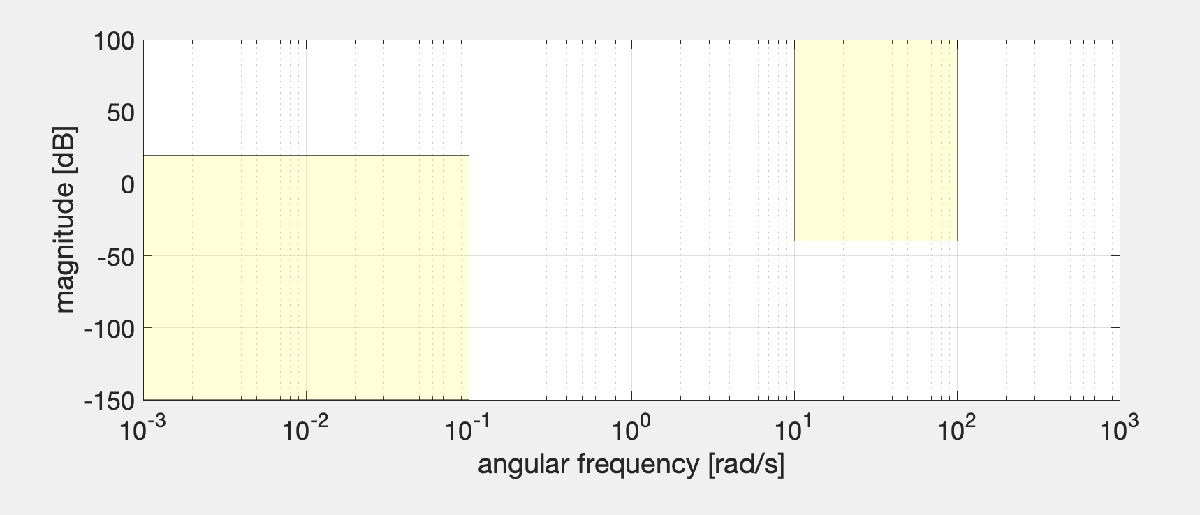

The **Bode** **diagram** of the **magnitude** $\left\vert L(j \omega)\right\vert_{\text{dB}}$ **should not cross these yellow regions**, and this graphical constraint provides valuable hints on the shape of the magnitude of the open-loop frequency response.				

As starting design configuration, let us set $\mu_C=1$ and check if $\left\vert L(j \omega)\right\vert_{\text{dB}}$ crosses the yellow regions. In case, modify $C(s)$ by adding zeros and/or additional poles.

### Answer to Question A1

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.		


$$G(s) = 2 \frac{(1+10\,s)}{(1+s)}$$


clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 2*(1+10*s)/(1+s); % the process G(s)

As starting configuration, consider the simple controller


$$C_1(s) = 1$$


muC = 1;
Cs = muC;

Ls = Cs * Gs


Ls =
 
  20 s + 2
  --------
   s + 1
 
Continuous-time transfer function.
Model Properties


#### First Approach: Using the Asymptotic Bode Diagrams

Let's draw the asymptotic and the effective Bode diagrams for $L(s)$

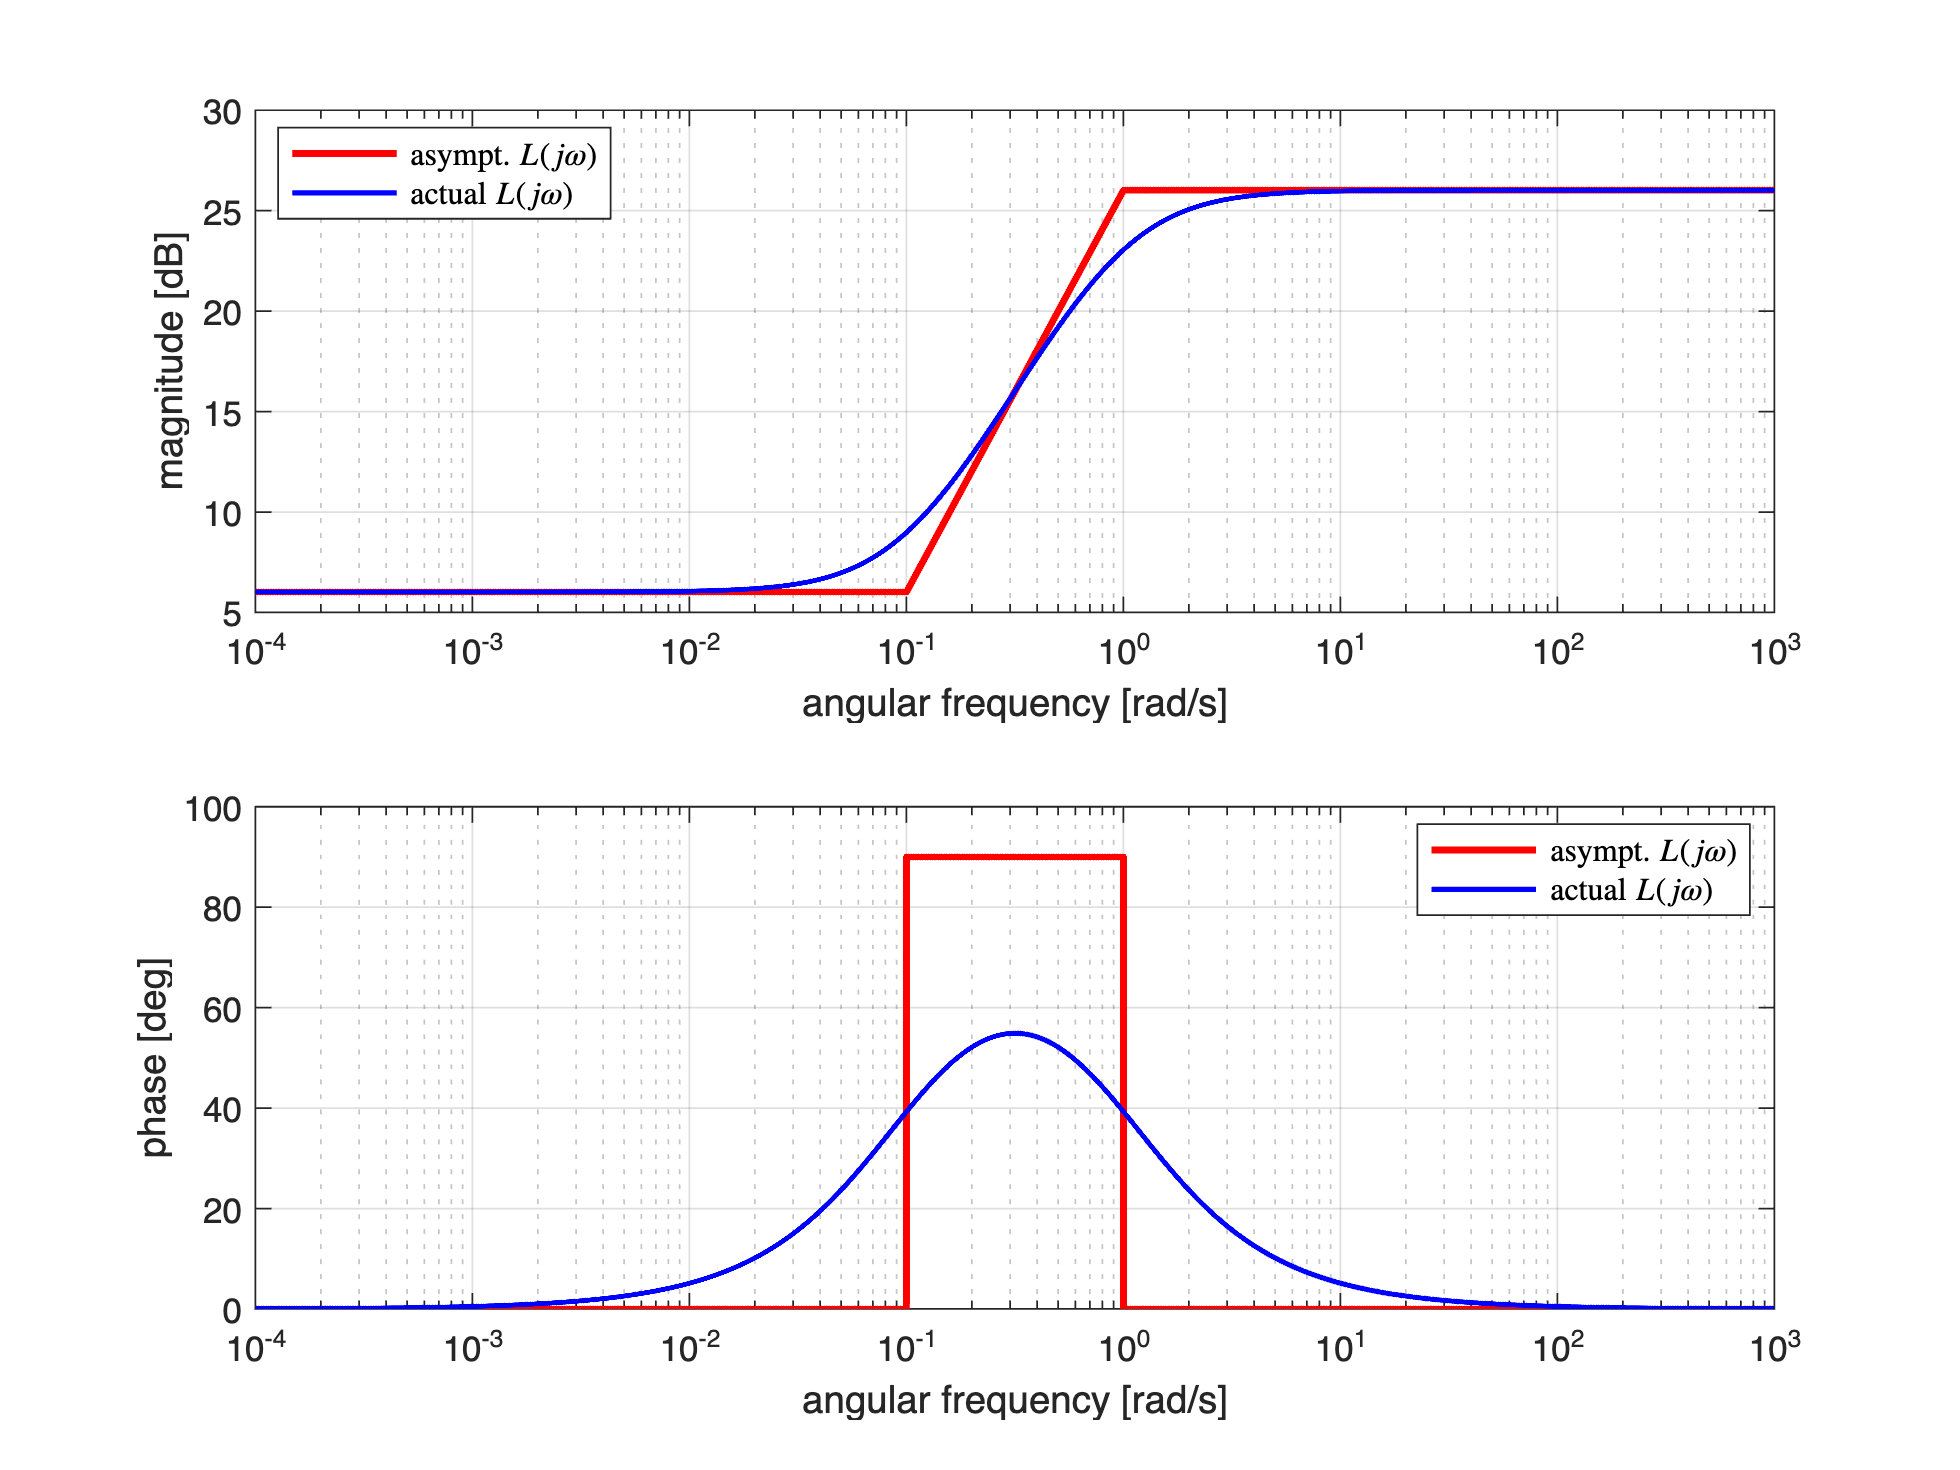

[ha1, ha2] = drawBodediagrams(Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Let us add the constraints on the magnitude $\left\vert L(j \omega)\right\vert_{\text{dB}}$

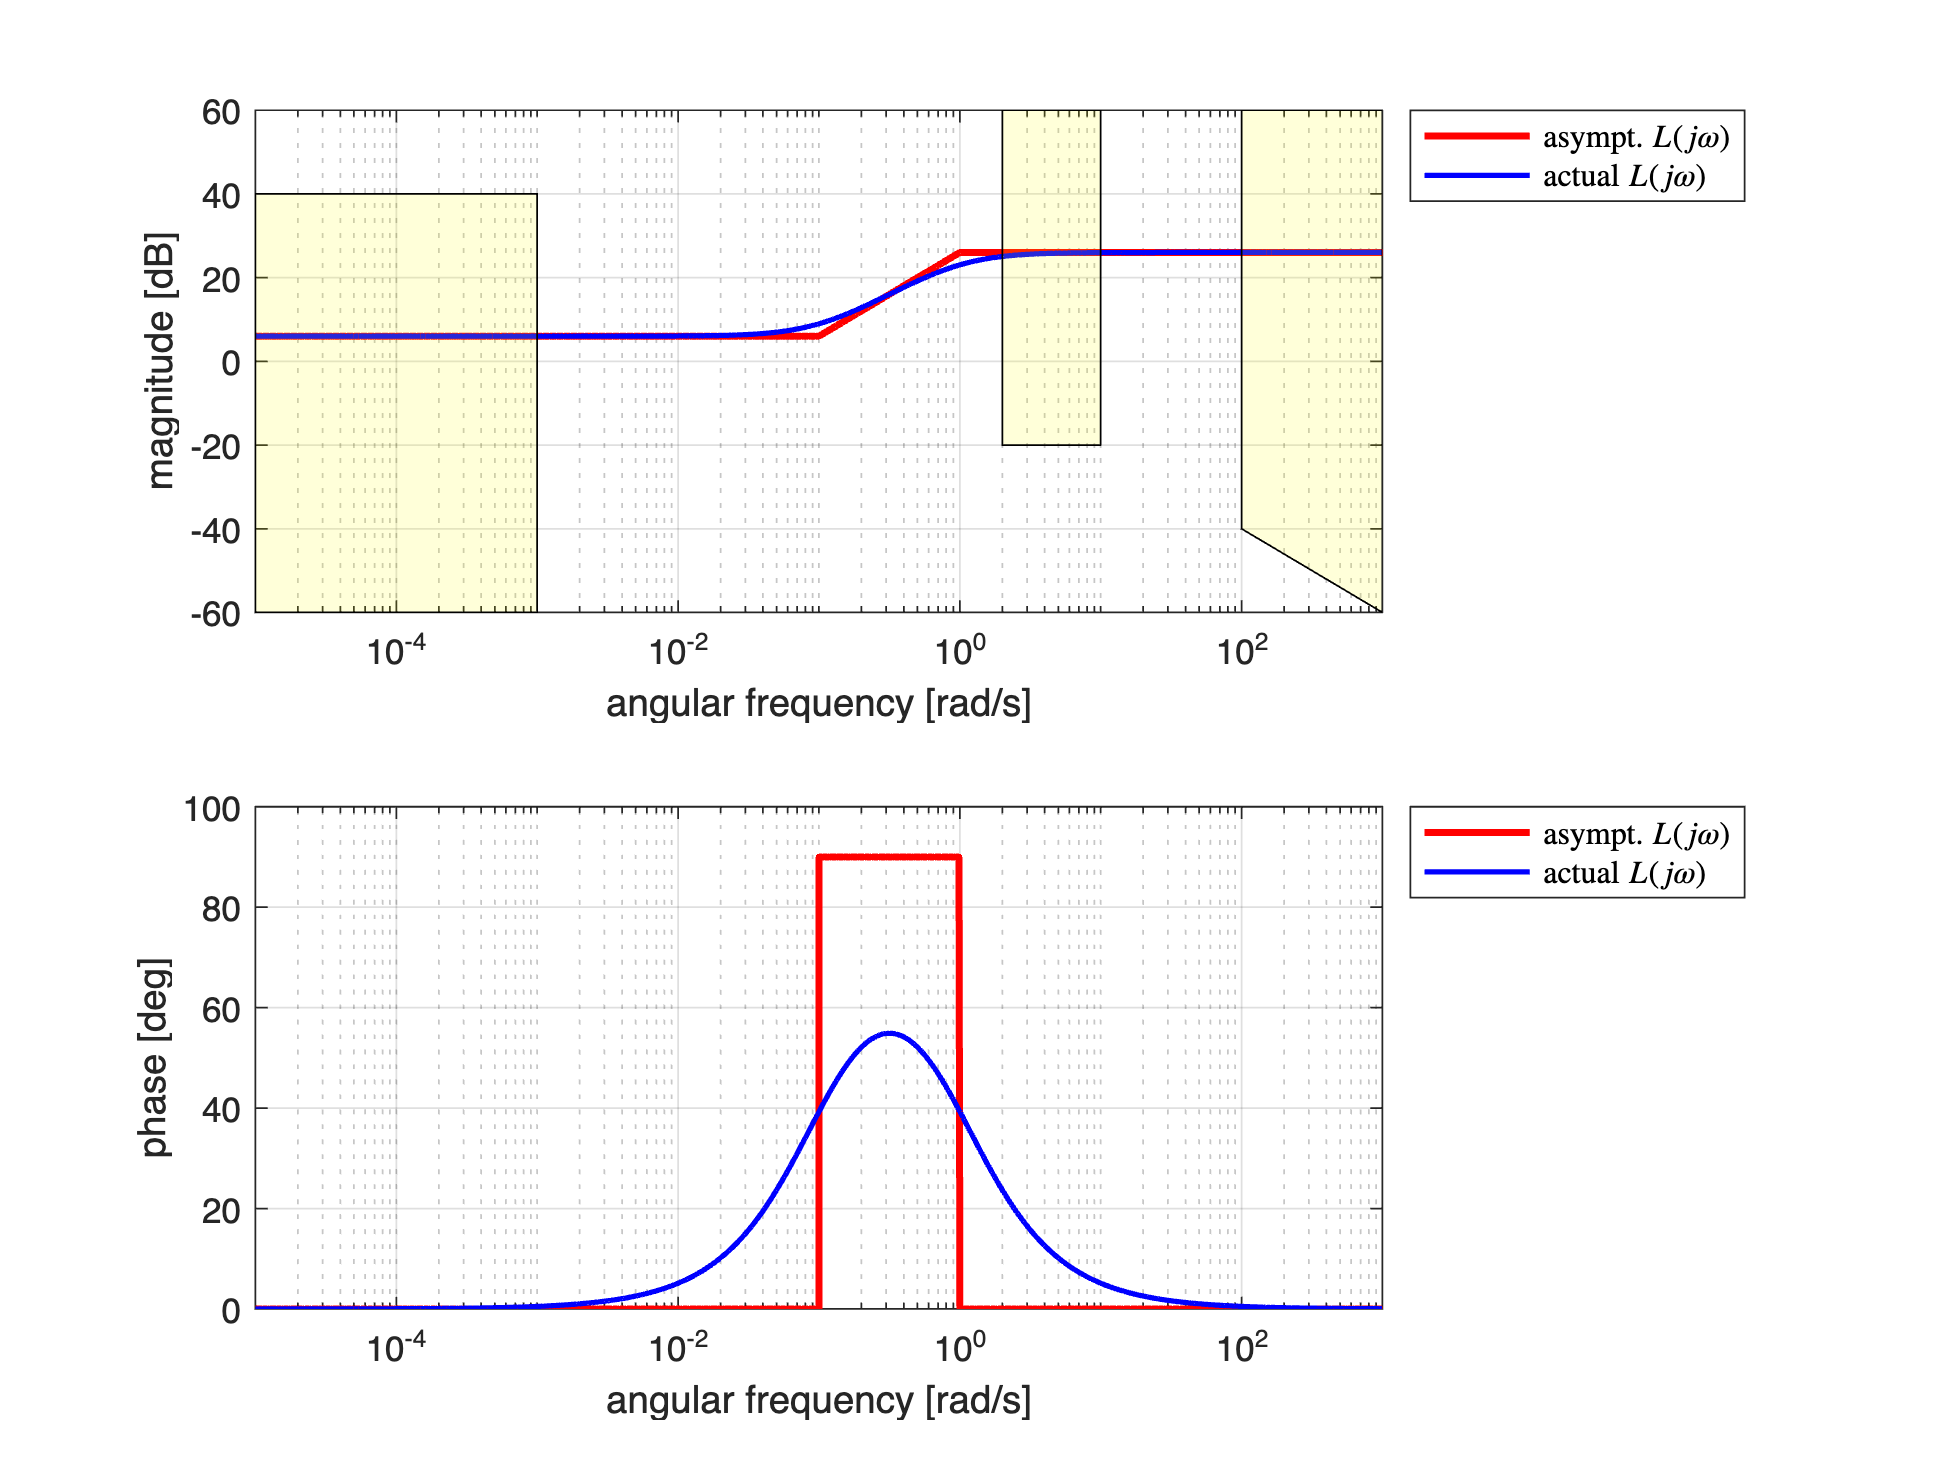

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-5, +3, 1e5); % 10000 values from 1e-5 up to 1e+3
[hax1, hax2] = drawBodediagrams(Ls, omVALS); % Bode diagram

ylim(hax1, [-60, +60]);

% the (A1.3) constraint
minOmega2 = 2.0;
maxOmega2 = 10.0;
LMAXdB = -20;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

% the (A1.4) & (A1.5) constraints
minOmega3 = 100.0;
maxOmega3 = 1000.0;
LMAXdB_left = -40;
LMAXdB_right = -60;
YLIMs = ylim(hax1);
Vert2 = [minOmega3 , LMAXdB_left; minOmega3 , YLIMs(2) ; ...
         maxOmega3 , YLIMs(2); maxOmega3 , LMAXdB_right];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (A1.2) constraint
minOmega1 = 1e-5;
maxOmega1 = 1e-3;
LMINdB = +40;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);



legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

Notice that setting $\mu_C = 1$does not meet the **requirements for the disturbance and noise attenuation**. Moreover, to fulfil those requirements we must modify the shape of $\left\vert L(j \omega)\right\vert_{\text{dB}}$.

#### Proposed Approach: the First Attempt

- Let's increase the static gain $\mu_L$, by choosing $\mu_C$ such that: $\mu_C \ge \frac{99}{2} \; \Longrightarrow\; \mu_C = 70$

- Let's insert two poles with time constants $\tau_1=\tau_2=100$, with the aim of bending the magnitude plot downwards;

- Insert also two zero with time constant $T=0.5$, with the aim of stop bending the magnitude plot.

- Check the resulting transfer function $L(s)$. 

**Note**: the requirement (A1.5) is not yet met. We will add at least one more pole to the controller later.

Thus


$$\bar C(s) = 55 \frac{(1+0.5\,s)^2}{(1+100\,s)^2}$$


muC = 70;
barCs = muC*((1+0.5*s)*(1+0.5*s))/((1+100*s)*(1+100*s));

% Note: by using minreal() we force the simplification of common factors in
% the numerator and the denominator polynomials
barLs = minreal(barCs * Gs)


barLs =
 
  0.035 s^3 + 0.1435 s^2 + 0.154 s + 0.014
  ----------------------------------------
     s^3 + 1.02 s^2 + 0.0201 s + 0.0001
 
Continuous-time transfer function.
Model Properties


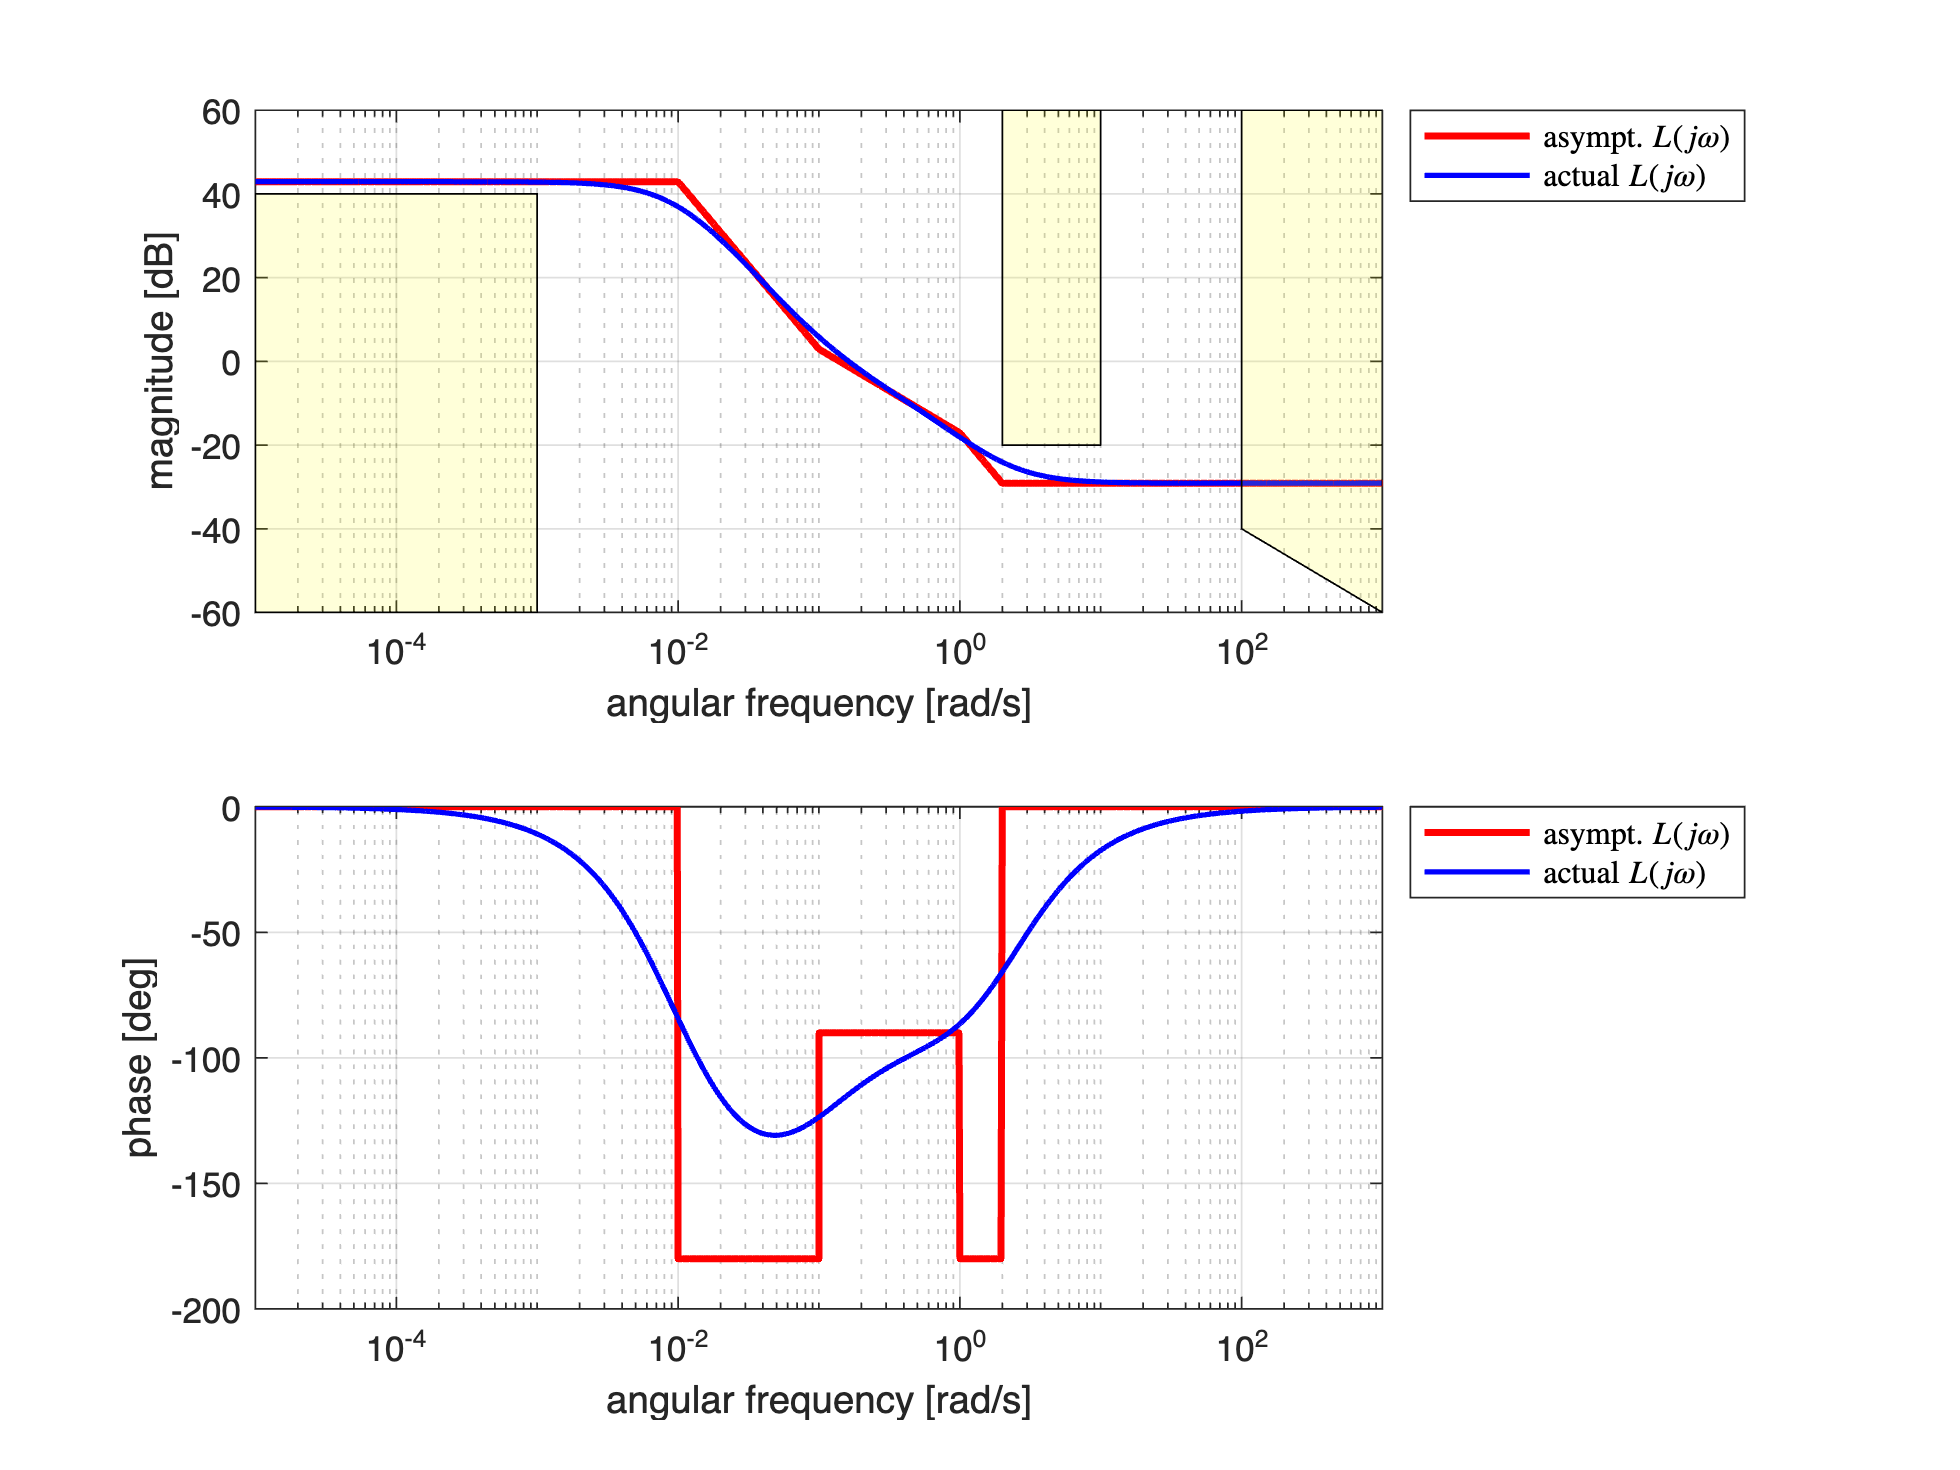


omVALS = logspace(-5, +3, 1e5); % 10000 values from 1e-5 up to 1e+3
[hax1, hax2] = drawBodediagrams(barLs, omVALS); % Bode diagram

ylim(hax1, [-60, +60]);

% the (A1.3) constraint
minOmega2 = 2.0;
maxOmega2 = 10.0;
LMAXdB = -20;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

% the (A1.4) & (A1.5) constraints
minOmega3 = 100.0;
maxOmega3 = 1000.0;
LMAXdB_left = -40;
LMAXdB_right = -60;
YLIMs = ylim(hax1);
Vert2 = [minOmega3 , LMAXdB_left; minOmega3 , YLIMs(2) ; ...
         maxOmega3 , YLIMs(2); maxOmega3 , LMAXdB_right];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (A1.2) constraint
minOmega1 = 1e-5;
maxOmega1 = 1e-3;
LMINdB = +40;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);



legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

The Req. (A1.3) is met (by visual inspection). The Reqs. (A1.4) and (A1.5) instead are not met.

Check if the constraints (A1.1) and (A1.2) are met

% A1.1
(dcgain(barLs) >= 99)

ans = logical
   1




% A1.2
( 20*log10( abs(freqresp(barLs, 0.001)) ) >= +40)

ans = logical
   1


#### Proposed Approach: the Second Attempt

Now we have to modify the controller, with the aim to fulfil the Reqs. (A1.4) and (A1.5). By adding a term in the polynomial at the denominator, with a real pole $p_3 = -100$, both the Reqs. should be met.


$$\bar C(s) = 70 \frac{(1+0.5\,s)^2}{(1+100\,s)^2 \,\left(1+0.1\,s\right)}$$


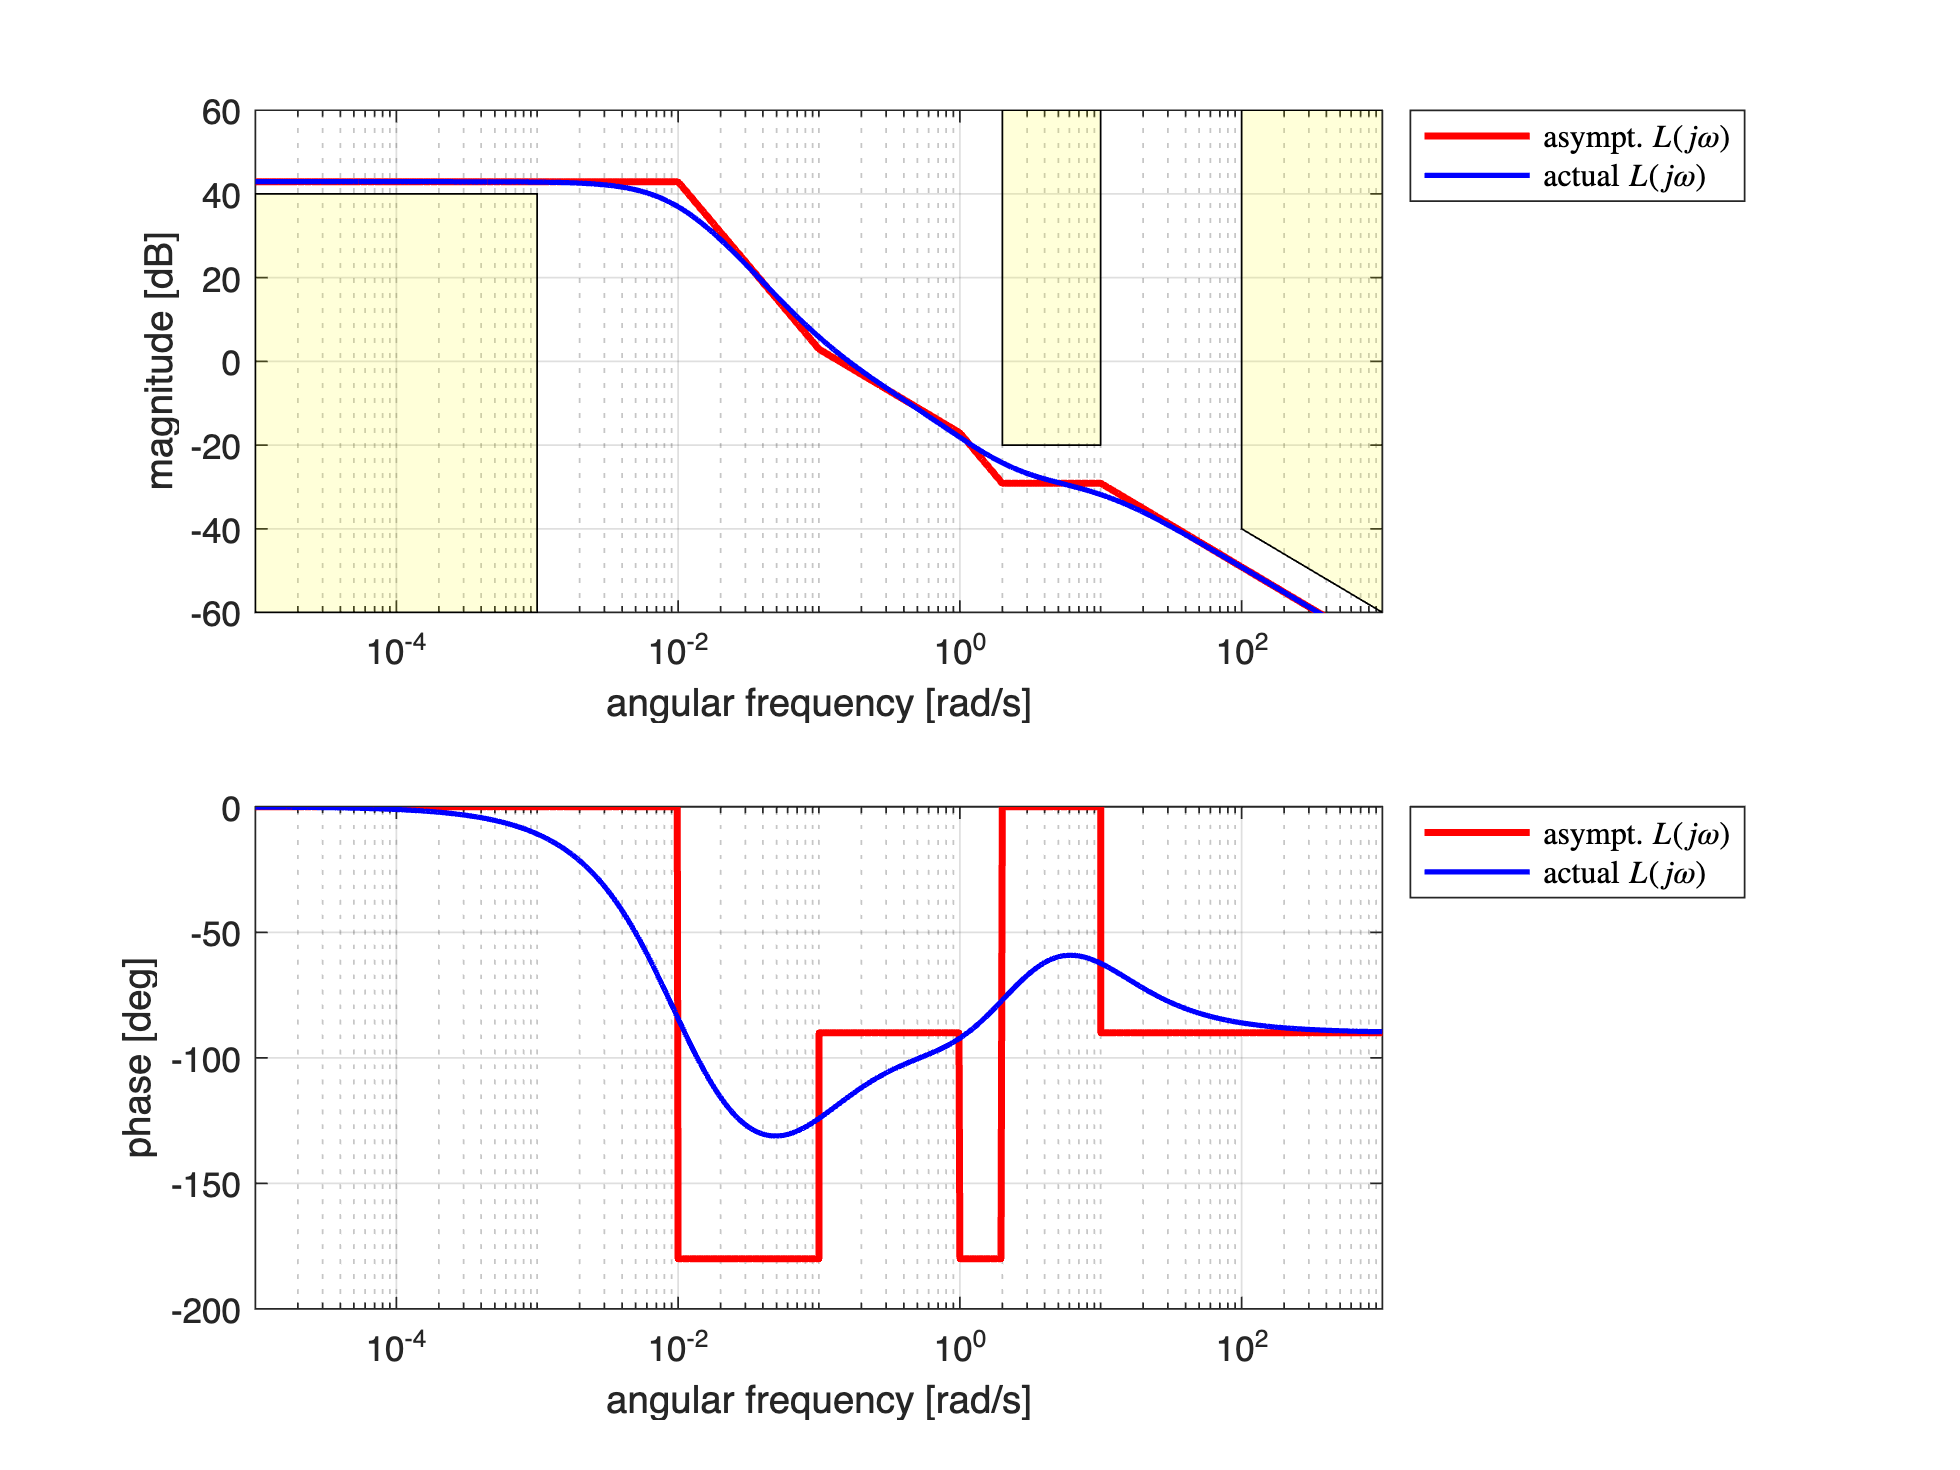

muC2 = 70;
barCs2 = muC2*((1+0.5*s)*(1+0.5*s))/((1+100*s)*(1+100*s)*(1+0.1*s));

% Note: by using minreal() we force the simplification of common factors in
% the numerator and the denominator polynomials
barLs2 = minreal(barCs2 * Gs);

omVALS = logspace(-5, +3, 1e5); % 10000 values from 1e-5 up to 1e+3
[hax1, hax2] = drawBodediagrams(barLs2, omVALS); % Bode diagram

ylim(hax1, [-60, +60]);

% the (A1.3) constraint
minOmega2 = 2.0;
maxOmega2 = 10.0;
LMAXdB = -20;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

% the (A1.4) & (A1.5) constraints
minOmega3 = 100.0;
maxOmega3 = 1000.0;
LMAXdB_left = -40;
LMAXdB_right = -60;
YLIMs = ylim(hax1);
Vert2 = [minOmega3 , LMAXdB_left; minOmega3 , YLIMs(2) ; ...
         maxOmega3 , YLIMs(2); maxOmega3 , LMAXdB_right];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (A1.2) constraint
minOmega1 = 1e-5;
maxOmega1 = 1e-3;
LMINdB = +40;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);



legend(hax1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')
legend(hax2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'bestoutside')

Check if the constraints (A1.1),  (A1.2) and (A1.4) are met

% A1.1
(dcgain(barLs2) >= 99)

ans = logical
   1



% A1.2
( 20*log10( abs(freqresp(barLs2, 0.001)) ) >= +40)

ans = logical
   1


%A1.4
( 20*log10( abs(freqresp(barLs2, 100)) ) <= -40)

ans = logical
   1


The Req. (A1.5) is met by construction, because now both the controller $C(s)$ and the transfer function $L(s)$ are strictly proper.

Let's analyse the stability margins:

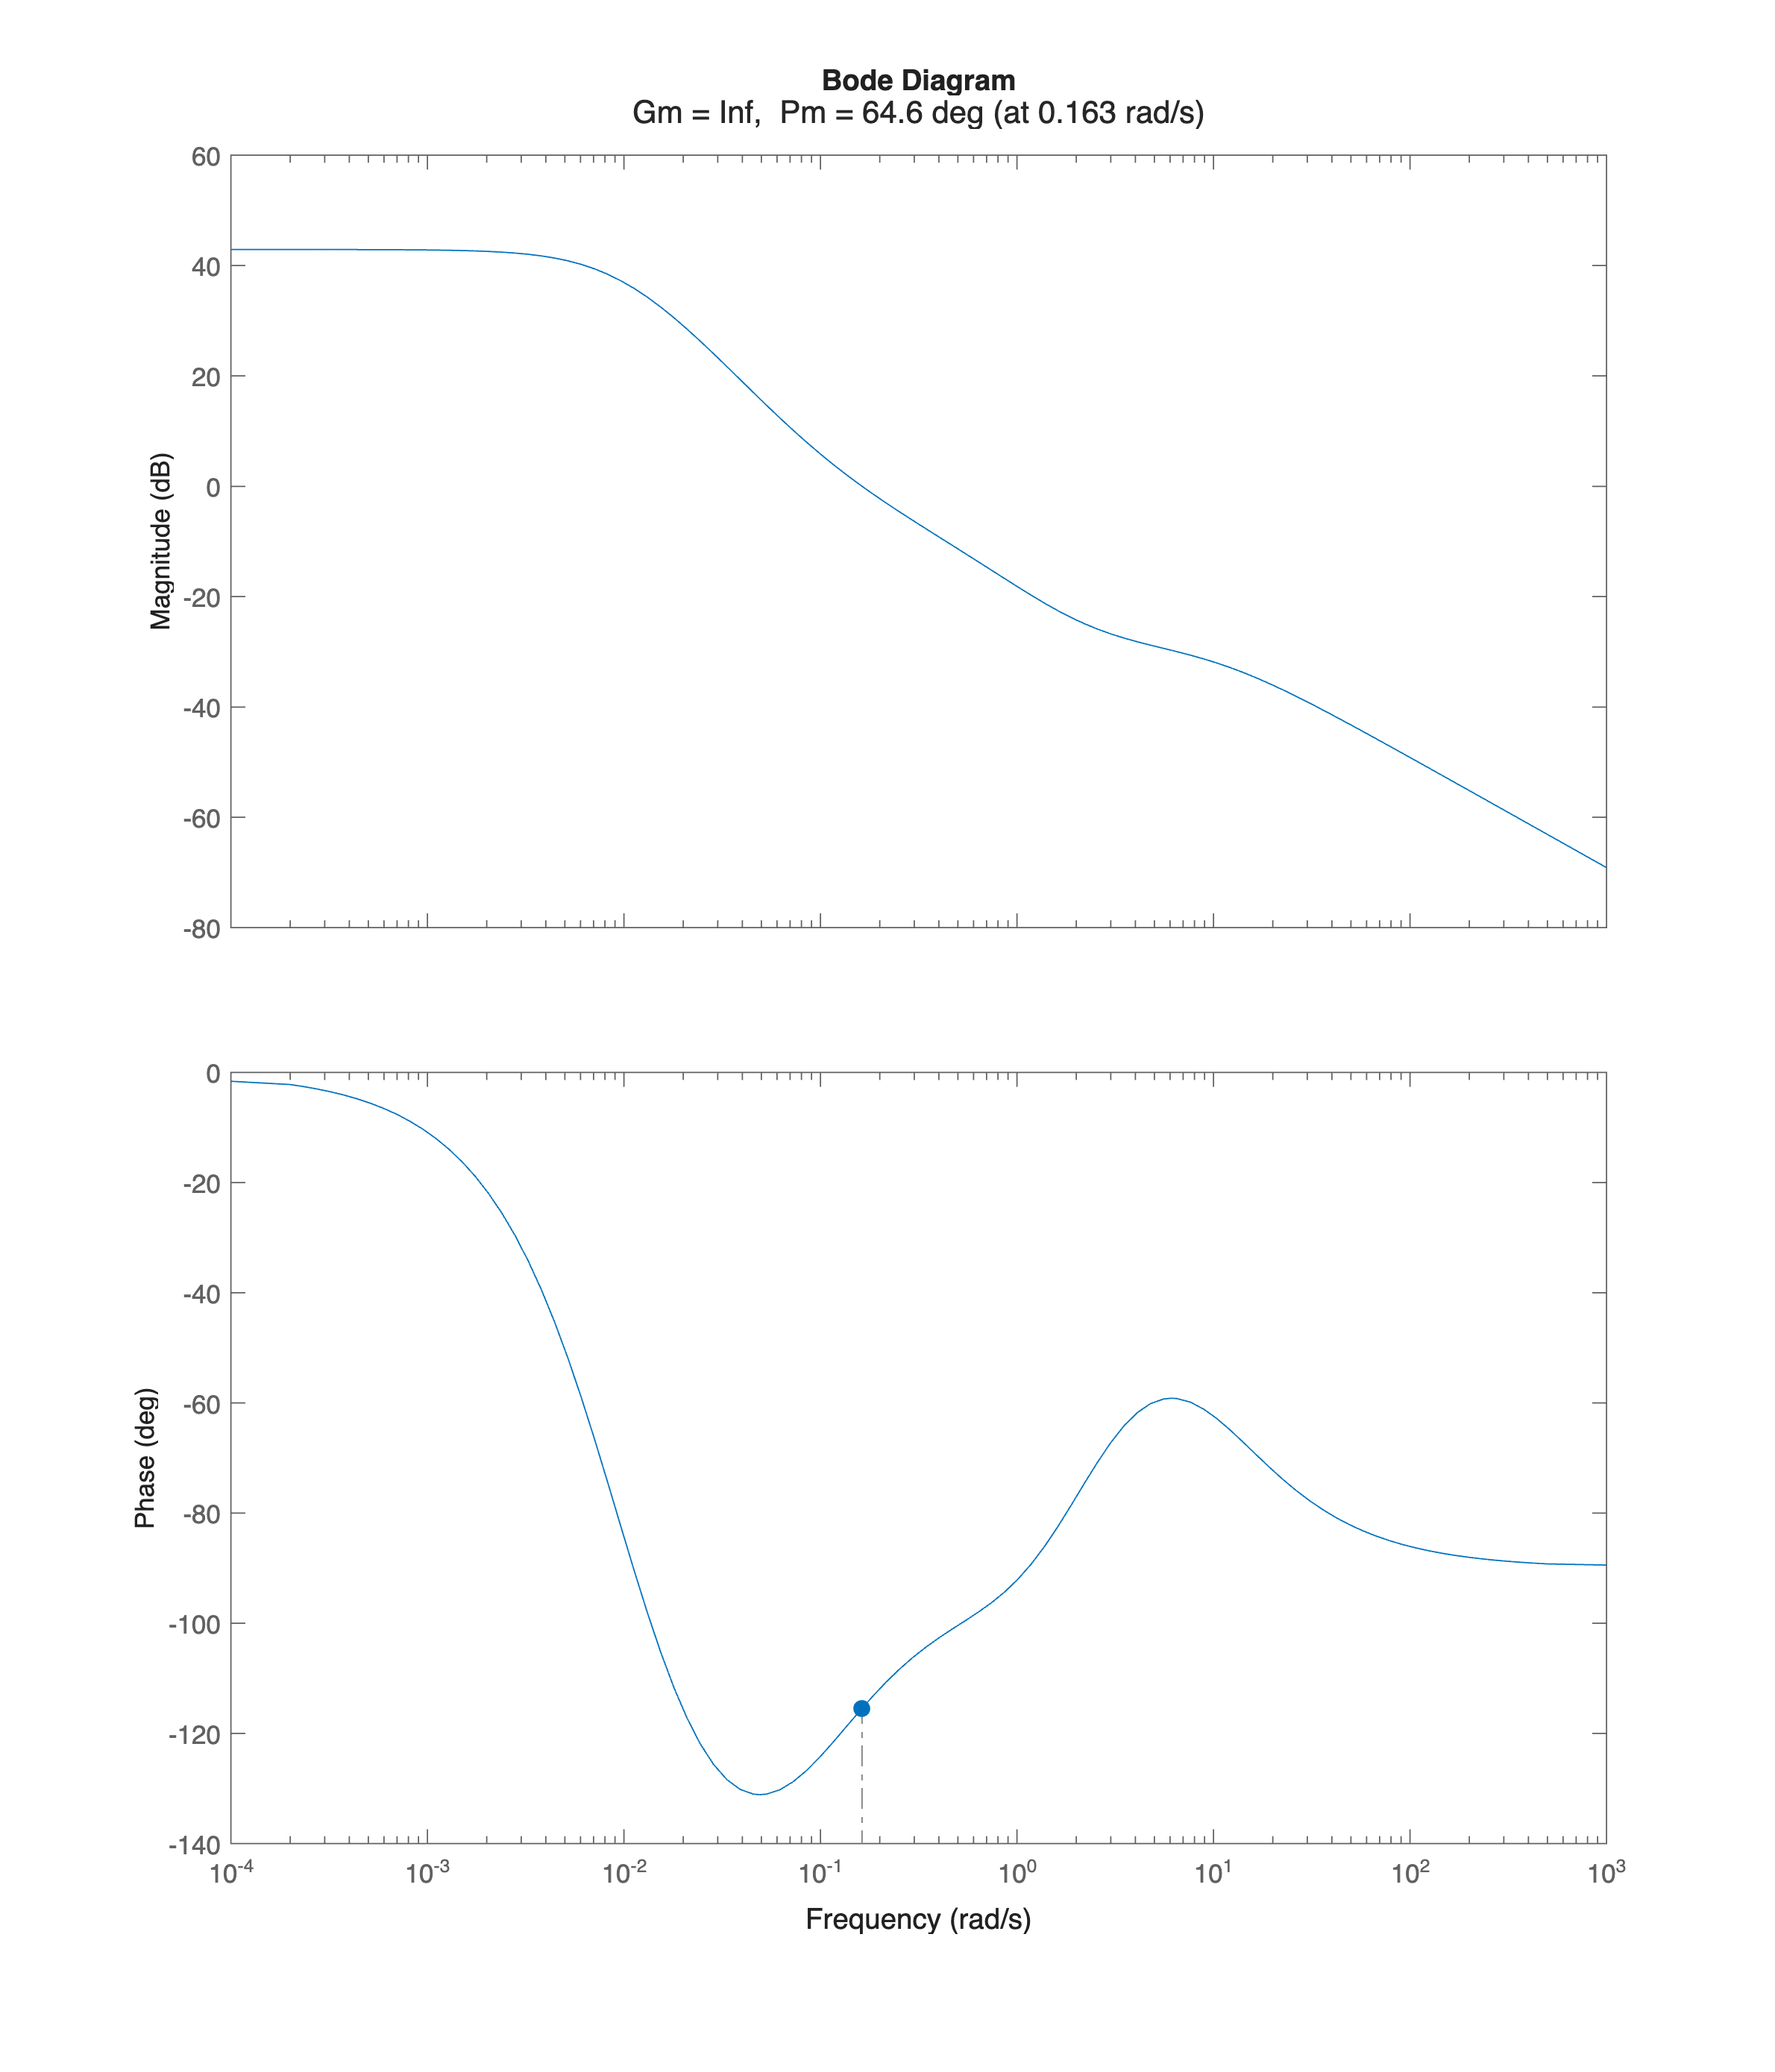

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(barLs2); 

The closed-loop system is asymptotically stable.

**All the requirements are met: the design has been completed.**

### **Fine Tuning using the Control System Designer App**

Let's analyse the control system performance using the controlSystemDesigner App:

controlSystemDesigner(Gs, barCs2)

No need for further tuning.

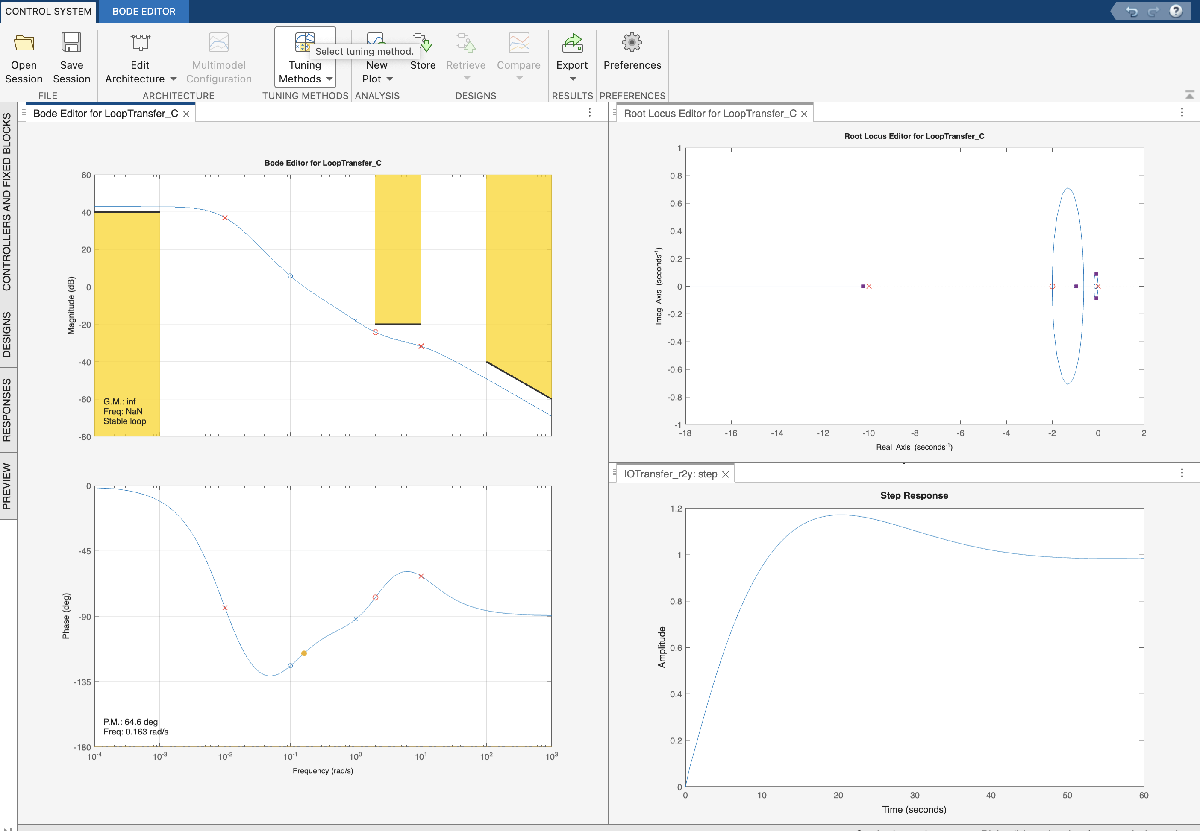

**Designer App session file**: `FA_2025-01-20-ControlSystemDesignerSession.mat`